load('samples\impulse_responses.mat');

[ySpeech, FsSpeech] = audioread('samples\clean_speech.wav');
[yNoise, FsNoise] = audioread('samples\artificial_nonstat_noise.wav');

sound(ySpeech, FsSpeech);

sound(yNoise, FsSpeech);

sound(ySpeech + yNoise, FsSpeech);

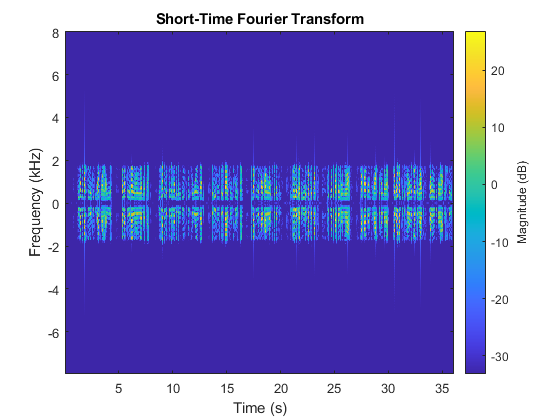

[S,F,T] = stft(ySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
cut = 100;
S(1:cut, :) = 0;
S((end-cut):end, :) = 0;
[iySpeech,tiSpeech] = istft(S,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
stft(iySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);

sound(iySpeech, FsSpeech);

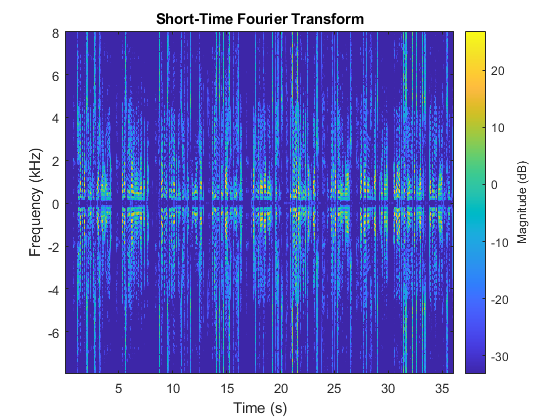

stft(ySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',15);

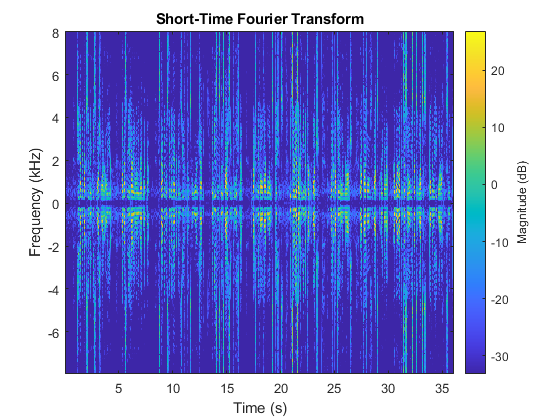

stft(ySpeech+yNoise,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',15);

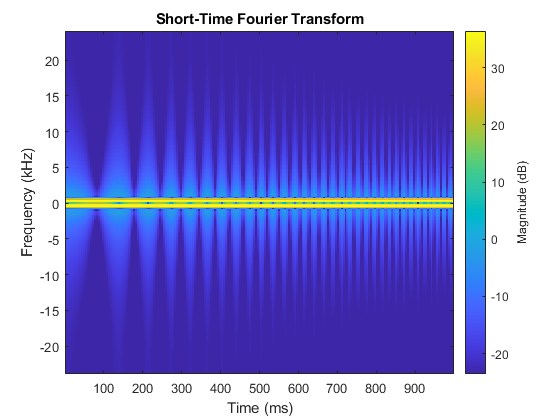

fs = 48000;
t = 0:1/fs:1-1/fs;
x = [chirp(t,100,1,300,'quadratic',45,'concave');
      chirp(t,200,1,600,'quadratic',[],'convex');
      chirp(t,300,1,500,'logarithmic')]'; 
x = [chirp(t, 300, 10, 600)]';
  
stft(x,fs,'Window',hamming(256,'periodic'),'OverlapLength',15);

[S,F,T] = stft(x,fs,'Window',hamming(256,'periodic'),'OverlapLength',15);

[ix,ti] = istft(S,fs,'Window',hamming(256,'periodic'),'OverlapLength',15);

plot(t,x(:,1)','LineWidth',1.5)
hold on
plot(ti,ix(:,1)','r--')
hold off
legend('Original Channel 1','Reconstructed Channel 1')

sound(0.5 * x, fs);

sound(0.5 * ix, fs);